% Varenyam Malhotra
% MATLAB Model of Variables in a Porcine Cardiac Xenotransplantation
% May 2023
% Begin MATLAB Model
% Measuring Blood Flow (q in porcine, Q in human) as a function of each variable 
% Where does porcine blood flow as a function of the kinematic viscosity of
% blood match up with human blood flow as a function of the kinematic
% viscosity of blood?
% Setting the range of the kinematic blood viscosity
u = 0.0001:0.001:0.015;
% Defining the porcine cardiac system equation
qofu = pi./(128*u);
% Defining the human circulatory system equation
Qofu = (exp(-4*pi*u)).*(((exp(4*pi*u))/(4*pi*u)));
figure
% Plotting, labeling, adding a title and legend, adjusting fonts
plot(u, qofu, u, Qofu, 'LineWidth', 2.0)
xl = xlabel('Kinematic Viscosity of Blood, cm^2/s')

xl =   Text (Kinematic Viscosity of Blood, cm^2/s) with properties:

                 String: 'Kinematic Viscosity of Blood, cm^2/s'
               FontSize: 11
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [0.0075 -10.9489 -1]
                  Units: 'data'

  Show all properties


fontsize(xl, 20, 'points')
yl = ylabel('Blood Flow Rate, m/s')

yl =   Text (Blood Flow Rate, m/s) with properties:

                 String: 'Blood Flow Rate, m/s'
               FontSize: 11
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [-8.1221e-04 125.0001 -1]
                  Units: 'data'

  Show all properties


fontsize(yl, 20, 'points')
lgd = legend('q(u) - porcine', 'Q(u) - human')

lgd =   Legend (q(u) - porcine, Q(u) - human) with properties:

         String: {'q(u) - porcine'  'Q(u) - human'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7223 0.8524 0.1687 0.0536]
          Units: 'normalized'

  Show all properties


fontsize(lgd, 36,'points')
t = title('Blood Flow Rate as a function of Porcine Blood Kinematic Viscosity')

t =   Text (Blood Flow Rate as a function of Porcine Blood Kinematic Viscosity) with properties:

                 String: 'Blood Flow Rate as a function of Porcine Blood Kinematic Viscosity'
               FontSize: 11
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'center'
               Position: [0.0075 251.0036 0]
                  Units: 'data'

  Show all properties


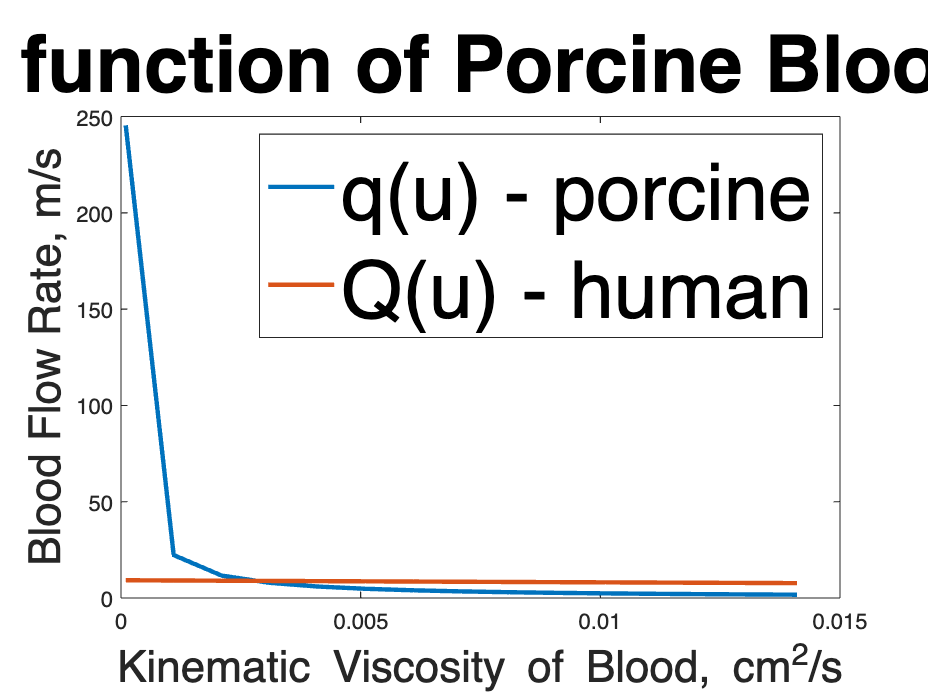

fontsize(t, 36, 'points')


% Where does porcine blood flow as a function of the blood pressure
% gradient match up with human blood flow, also as a function of the blood
% pressure gradient? 
% Setting the range of the blood pressure gradient
pz = 40:1:100;
% Defining the porcine cardiac system equation
qofpz = ((pi/128)*pz)*(4.3^4);
% Defining the human circulatory system equation
Qofpz = ((4.3)^2*pz)/(2*1.1);
% 4.3 in place for diameter and cross-sectional area (explained in paper)
figure
% Plotting, labeling, adding a title and legend, adjusting fonts
plot(pz, qofpz, pz, Qofpz, 'LineWidth', 2.0)
xl = xlabel('Blood Pressure Gradient, mm Hg')

xl =   Text (Blood Pressure Gradient, mm Hg) with properties:

                 String: 'Blood Pressure Gradient, mm Hg'
               FontSize: 11
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [70.0000 273.7226 -1]
                  Units: 'data'

  Show all properties


fontsize(xl, 20, 'points')
yl = ylabel('Blood Flow Rate, m/s')

yl =   Text (Blood Flow Rate, m/s) with properties:

                 String: 'Blood Flow Rate, m/s'
               FontSize: 11
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [36.7512 600.0003 -1]
                  Units: 'data'

  Show all properties


fontsize(yl, 20, 'points')
lgd = legend('q(pz) - porcine', 'Q(pz) - human')

lgd =   Legend (q(pz) - porcine, Q(pz) - human) with properties:

         String: {'q(pz) - porcine'  'Q(pz) - human'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7143 0.8524 0.1768 0.0536]
          Units: 'normalized'

  Show all properties


fontsize(lgd, 36, 'points')
t = title('Blood Flow Rate as a function of Blood Pressure Gradient')

t =   Text (Blood Flow Rate as a function of Blood Pressure Gradient) with properties:

                 String: 'Blood Flow Rate as a function of Blood Pressure Gradient'
               FontSize: 11
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'center'
               Position: [70.0000 902.4088 0]
                  Units: 'data'

  Show all properties


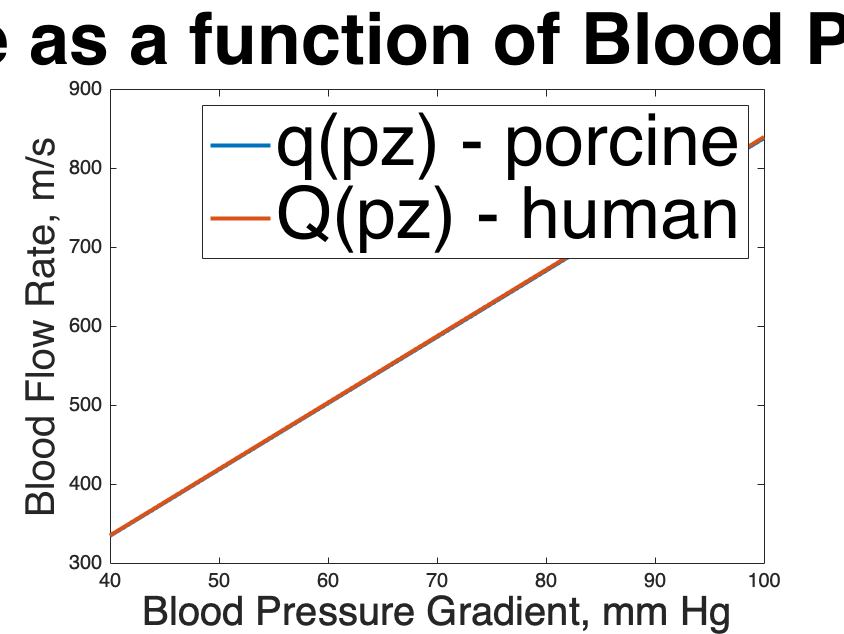

fontsize(t, 36, 'points')

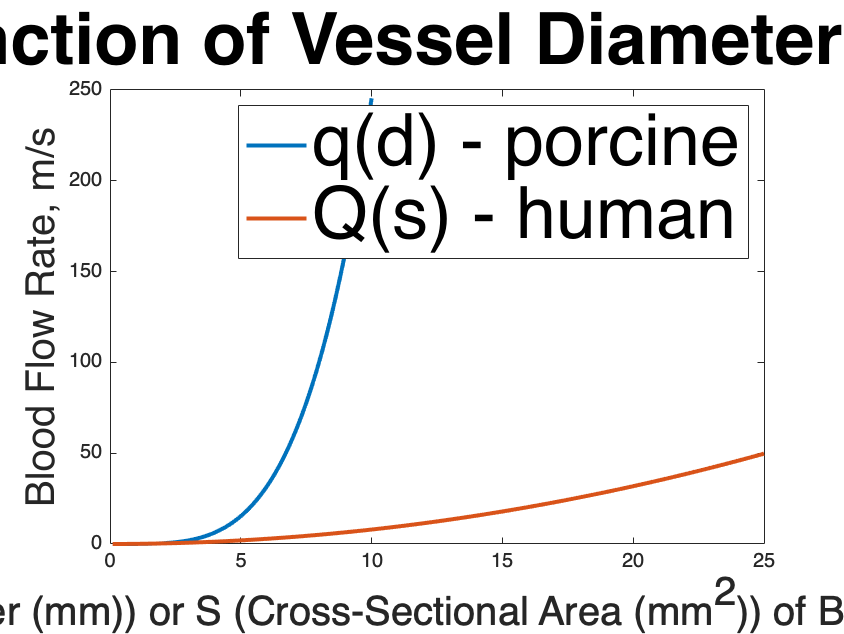


% Where does porcine blood flow as a function of blood vessel
% cross-sectional area match up with human blood flow as a function of the
% Diameter of a blood vessel?
% Setting the range of the blood vessel diameter
d = 0.1:0.1:10;
% Setting the range of the blood vessel cross-sectional area
s = 0.1:0.1:25;
% Defining the porcine cardiac system equation
qofd = (pi/128)*(d.^4);
% Defining the human circulatory system equation
Qofs = exp((-4*pi)./s).*(((s.^2.*(exp((4*pi)./s)))/(4*pi)));
figure;
% Plotting, labeling, adding a title and legend, adjusting fonts
plot(d, qofd, s, Qofs, 'LineWidth', 2.0);
xl = xlabel('D (Diameter (mm)) or S (Cross-Sectional Area (mm^2)) of Blood Vessels');
fontsize(xl, 20, 'points')
yl = ylabel('Blood Flow Rate, m/s');
fontsize(yl, 20, 'points')
lgd = legend('q(d) - porcine', 'Q(s) - human');
fontsize(lgd, 36, 'points')
t = title('Blood Flow Rate as function of Vessel Diameter & Cross-Sectional Area');
fontsize(t, 36, 'points')